## Punto 4

- Primero ejecutar el archivo FIR_Design

- Definir las ganancias deseadas

- Importar la entrada y cambiar el nombre del archivo en auidoread("name.wav")( Debe estar muestreado a 64 kHz)

- Si no se tiene una señal de entrada específica, se pueden utilizar señales de ejemplo al descomentarlas

### Definición de parámetros y entrada

% Cuarto Punto
t = 0:1/fs:1; % Tiempo de 1 segundo

% Definición de la ganacia 
G1 = 2;
G2 = 1.2;
G3 = 1.9;
G4 = 2;

%=============== Eliga la entrada deseada

%X = chirp(t, 20, t(end), fs/2);   % 20 Hz → 32 kHz


% [X, fs] = audioread("Ikkimel_WHOS_THAT.wav");   % audio File

% if size(X,2) > 1
%     X = mean(X, 2);% Convert to mono
% end

X = sin(2*pi*1000*t); % Señal de entrada (1 kHz)

%X = randn(64000,1);  % white Gaussian noise

%X = zeros(64000,1);% Impulse
%X(1) = 1;% Impulse


audiowrite('beforeFIR.wav', X, fs);



### Espectro señal de entrada

% --- SNIPPET: espectro de entrada en dBFS (0 dB => tono amplitude 1) ---
% Asume X y fs definidos. X debe estar en rango [-1,1] si quieres dBFS real.
X = X(:);
N = length(X);           % usa la longitud real o un Nfft mayor si quieres interpolar
Nfft = fs;             % resolución en frecuencia (puedes ajustar)
half = 1:floor(Nfft/2)+1;
f_pos = (0:Nfft/2)*(fs/Nfft);

% FFT
X_fft = fft(X, Nfft);

% Single-sided magnitude normalizada para que un tono a amp=1 -> 1 (0 dB)
X_mag_single = abs(X_fft(half)) * (2 / N);   % IMPORTANT: dividir por N, multiplicar por 2
% Ajuste: si DC o Nyquist presentes, no doble esos bins (no crítico para tono no-DC)

% Convertir a dBFS
X_mag_dbFS = 20*log10(X_mag_single + eps);

% Encontrar pico
[peak_mag, idxPeak] = max(X_mag_single);
peak_freq = f_pos(idxPeak);
peak_mag_dbFS = X_mag_dbFS(idxPeak);

fprintf('Entrada: pico = %.6g (linear), %.2f dBFS en %.2f Hz\n', peak_mag, peak_mag_dbFS, peak_freq);

Entrada: pico = 0.999984 (linear), -0.00 dBFS en 1000.00 Hz


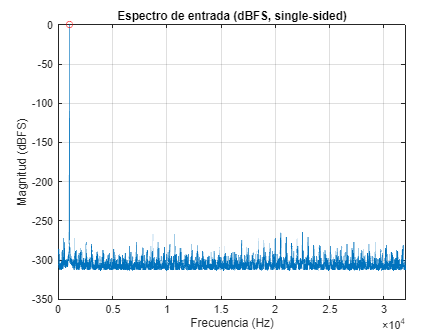


% Plot
figure;
plot(f_pos, X_mag_dbFS, 'LineWidth',1); grid on;
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dBFS)');
title('Espectro de entrada (dBFS, single-sided)');
xlim([0 fs/2]);
hold on; plot(peak_freq, peak_mag_dbFS, 'ro'); hold off;

## Primera Etapa - aplicación de cada filtro a la entrada


% Sistema con filtros FIR

%Nfft = 4096; % resolución de 15.625 Hz

y1 = fftfilt(B1,X,Nfft);
y2 = fftfilt(B2,X,Nfft);
y3 = fftfilt(B3,X,Nfft);
y4 = fftfilt(B4,X,Nfft);


### Respuestas en magnitud y fase de cada filtro ante la entrada

y1: salida @ 1000.0 Hz = -76.29 dBFS (atenuación 76.29 dB)


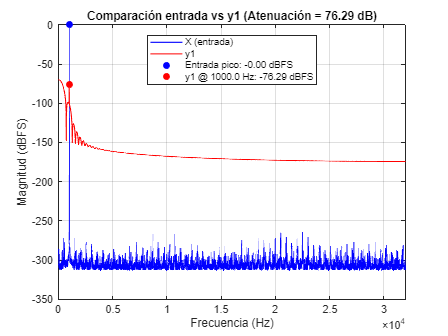

y2: salida @ 1000.0 Hz = -0.08 dBFS (atenuación 0.08 dB)


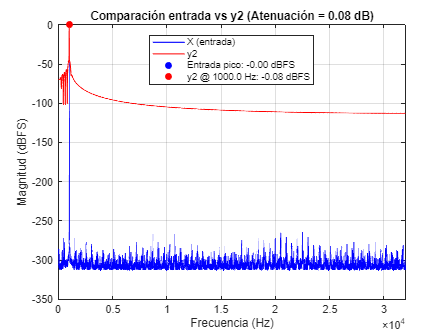

y3: salida @ 1000.0 Hz = -9.19 dBFS (atenuación 9.19 dB)


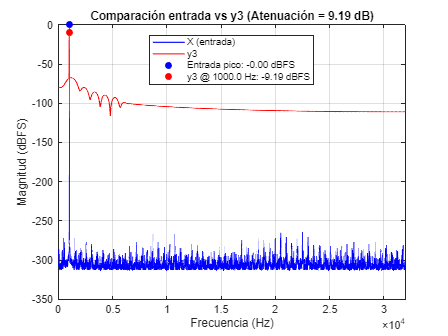

y4: salida @ 1000.0 Hz = -45.92 dBFS (atenuación 45.92 dB)


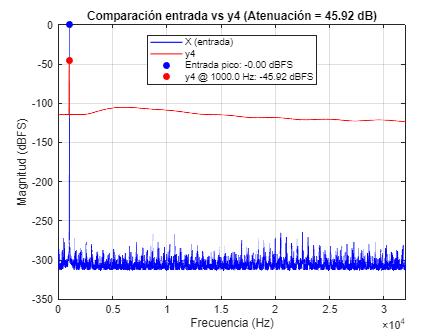

%% --- SNIPPET: espectro de salida para y1, y2, y3, y4 ---
% Usa: X, fs, y1..y4, Nfft, peak_freq, peak_mag_dbFS, f_pos, half

Ys = {y1(:), y2(:), y3(:), y4(:)};
names = {'y1','y2','y3','y4'};

for k = 1:4
    y = Ys{k};            % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude (mismo método que entrada)
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Magnitud a la frecuencia del pico de entrada
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Atenuación = diferencia en dBFS
    attenuation = peak_mag_dbFS - Y_mag_at_peak_dbFS;

    fprintf('%s: salida @ %.1f Hz = %.2f dBFS (atenuación %.2f dB)\n', ...
        names{k}, peak_freq, Y_mag_at_peak_dbFS, attenuation);

    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');
    plot(peak_freq, Y_mag_at_peak_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico: %.2f dBFS', peak_mag_dbFS), ...
           sprintf('%s @ %.1f Hz: %.2f dBFS', names{k}, peak_freq, Y_mag_at_peak_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');
    title(sprintf('Comparación entrada vs %s (Atenuación = %.2f dB)', names{k}, attenuation));
    grid on; xlim([0 fs/2]);
end

## Segunda Etapa - Cambio de Amplitud por ganancias G1, G2, G3 y G4 


yG1 = y1 * G1;
yG2 = y2 * G2;
yG3 = y3 * G3;
yG4 = y4 * G4;

### Comparación de Espectros en la segunda etapa

yG1: salida @ 1000.0 Hz = -70.27 dBFS (atenuación 70.27 dB)


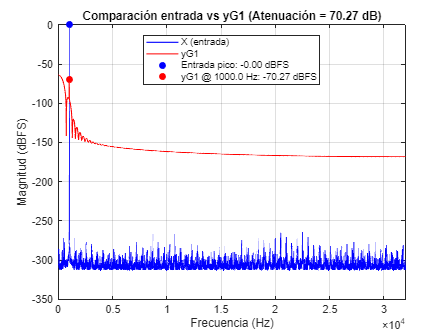

yG2: salida @ 1000.0 Hz = 1.50 dBFS (atenuación -1.50 dB)


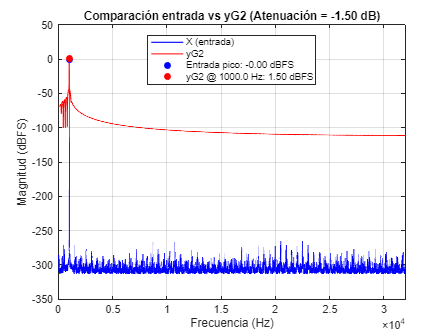

yG3: salida @ 1000.0 Hz = -3.62 dBFS (atenuación 3.62 dB)


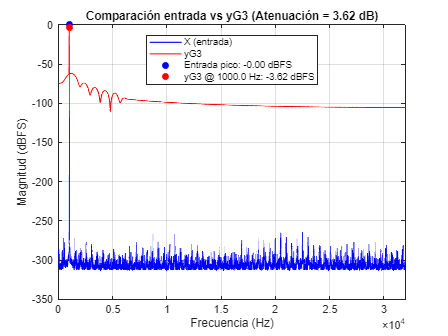

yG4: salida @ 1000.0 Hz = -39.90 dBFS (atenuación 39.90 dB)


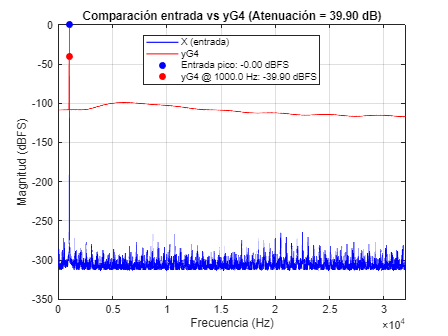

Ys = {yG1(:), yG2(:), yG3(:), yG4(:)};
names = {'yG1','yG2','yG3','yG4'};

for k = 1:4
    y = Ys{k};            % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude (mismo método que entrada)
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Magnitud a la frecuencia del pico de entrada
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Atenuación = diferencia en dBFS
    attenuation = peak_mag_dbFS - Y_mag_at_peak_dbFS;

    fprintf('%s: salida @ %.1f Hz = %.2f dBFS (atenuación %.2f dB)\n', ...
        names{k}, peak_freq, Y_mag_at_peak_dbFS, attenuation);

    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');
    plot(peak_freq, Y_mag_at_peak_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico: %.2f dBFS', peak_mag_dbFS), ...
           sprintf('%s @ %.1f Hz: %.2f dBFS', names{k}, peak_freq, Y_mag_at_peak_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');
    title(sprintf('Comparación entrada vs %s (Atenuación = %.2f dB)', names{k}, attenuation));
    grid on; xlim([0 fs/2]);
end

## Tercera Etapa - Y_final (sumador)

%Ganancias + sumador
y_final = yG1 + yG2 + yG3 + yG4;


Ys = {y_final(:)};
names = {'y_{final}'};

k=1

k = 1

    y = Ys{k};            % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude (mismo método que entrada)
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Magnitud a la frecuencia del pico de entrada
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Atenuación = diferencia en dBFS
    attenuation = peak_mag_dbFS - Y_mag_at_peak_dbFS;

    fprintf('%s: salida @ %.1f Hz = %.2f dBFS (atenuación %.2f dB)\n', ...
        names{k}, peak_freq, Y_mag_at_peak_dbFS, attenuation);

y_{final}: salida @ 1000.0 Hz = -2.01 dBFS (atenuación 2.01 dB)


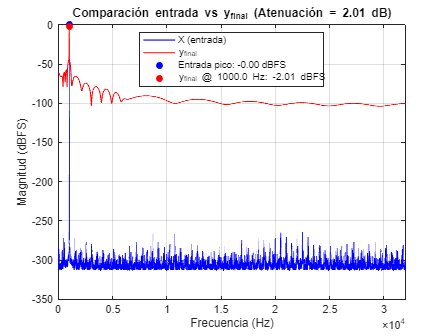


    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');
    plot(peak_freq, Y_mag_at_peak_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico: %.2f dBFS', peak_mag_dbFS), ...
           sprintf('%s @ %.1f Hz: %.2f dBFS', names{k}, peak_freq, Y_mag_at_peak_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');
    title(sprintf('Comparación entrada vs %s (Atenuación = %.2f dB)', names{k}, attenuation));
    grid on; xlim([0 fs/2]);

% Normalize to prevent clipping (optional but safe)
y_final = y_final / max(abs(y_final));

% Save filtered output to a new audio file
audiowrite("AfterFIR.wav", y_final, fs);


